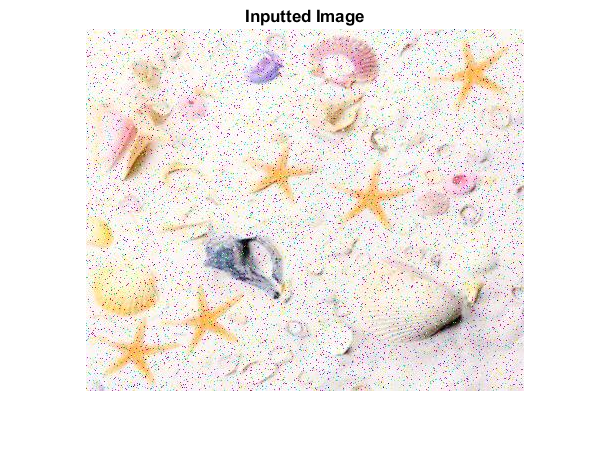

clear;
clc;

% Reading in the filename
starfish = imread("..\images\starfish.jpg");
imshow(starfish);
title("Inputted Image");

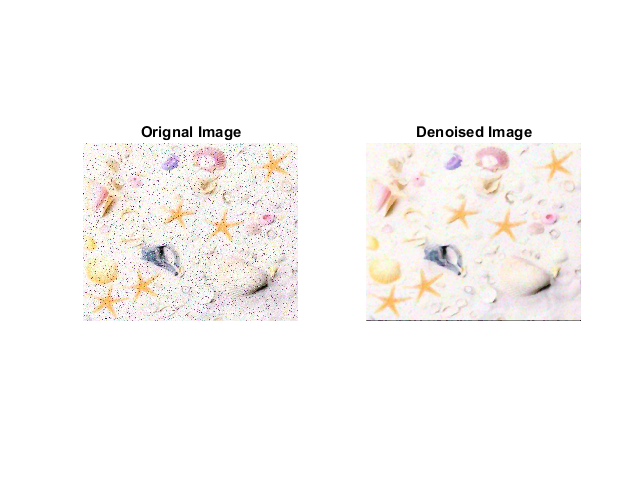

% Denoising the image using a function.
[denoised_starfish] = denoise_func(starfish);

% Uses median filter to remove the noise 
% The RGB image is passed to the function to remove all noise from the
% each colour channel

% Showing image
figure;
hold on;
    subplot(1,2,1), imshow(starfish);
    title("Orignal Image");
    subplot(1,2,2), imshow(denoised_starfish);
    title("Denoised Image");
hold off;

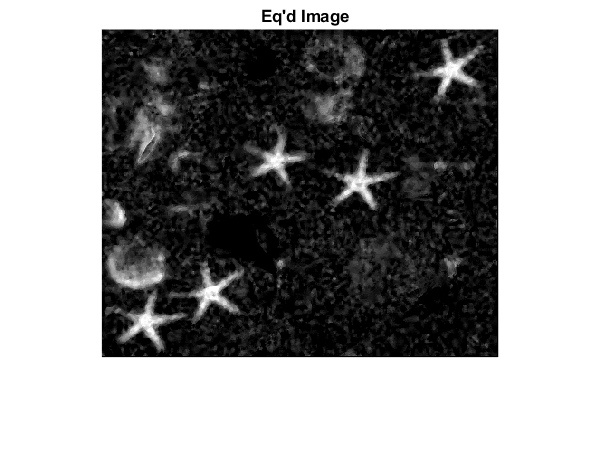

close;
% Returns the eq'd image so that it can be used elsewhere 
[starfish_eq] = adjust_func(denoised_starfish);

% Showing image
figure;
hold on;
    subplot(1,1,1), imshow(starfish_eq);
    title("Eq'd Image");
hold off;

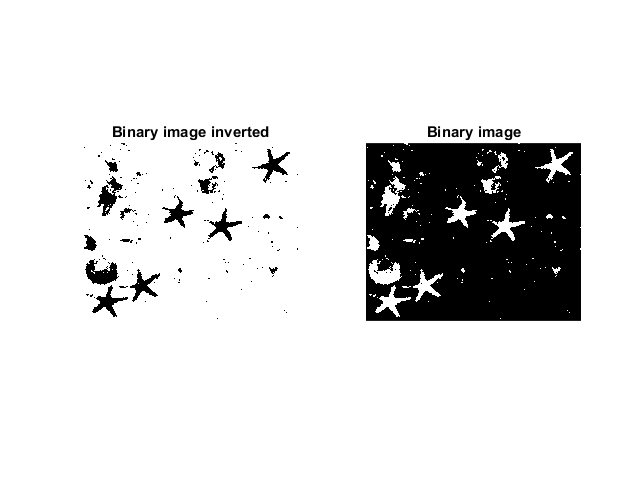

close;

% Creating the threshold value 
greythresh_starfish = graythresh(starfish_eq);

% Creating a binary image using the eq'd image and the threshold image
 bin_starfish_invert = imcomplement(imbinarize(starfish_eq, greythresh_starfish));
 bin_starfish = (imbinarize(starfish_eq, greythresh_starfish));

% Showing image
figure;
hold on;
    subplot(1,2,1), imshow(bin_starfish_invert);
    title("Binary image inverted");
    subplot(1,2,2), imshow(bin_starfish);
    title("Binary image");
hold off;

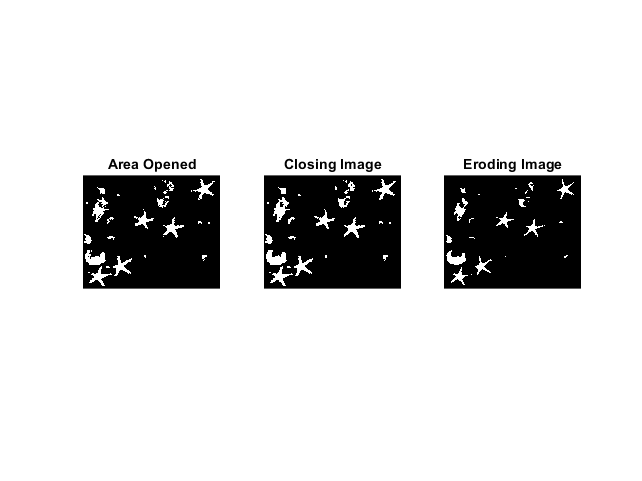

close;

% clearing up the image before sending to the seperator function
% strel value set to sphere with the radius of 2 
se_disk_4 = strel('sphere',2);

% bwareaopen removes moves small objects from the image
% in this case it removes any object that contains fewer than 20 pixels
area_opening = bwareaopen(bin_starfish,20);

% Fills in holes that may have occurred due to noise
closing = imclose(area_opening, se_disk_4);

% Erodes the image slighly to make sure non starfish objects are touching
% starfish
eroding = imerode(closing, se_disk_4);

% Showing image
figure;
hold on;
    subplot(1,3,1), imshow(area_opening);
    title("Area Opened");
    subplot(1,3,2), imshow(closing);
    title("Closing Image");
    subplot(1,3,3), imshow(eroding);
    title("Eroding Image");
hold off;

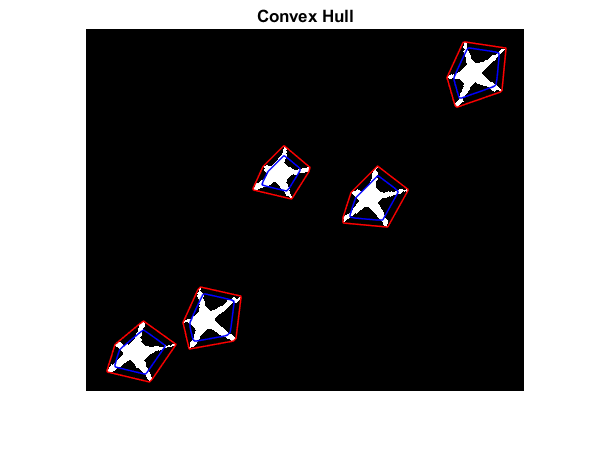

close;

% Finds all the connected components  in the binary image
% connectivity of 8 is default, but 4 does a better job 
CC = bwconncomp(eroding,4);

% Starfish separator function, uses HullConvex to remove starfish fins then
% counts them 
[starfish_sep] = starfish_separator_func(eroding, CC);

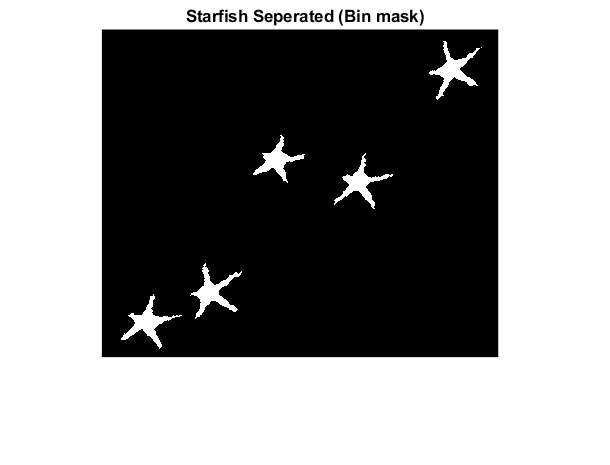


% Showing image
figure;
hold on;
    subplot(1,1,1), imshow(starfish_sep);
    title("Starfish Seperated (Bin mask)");
hold off;

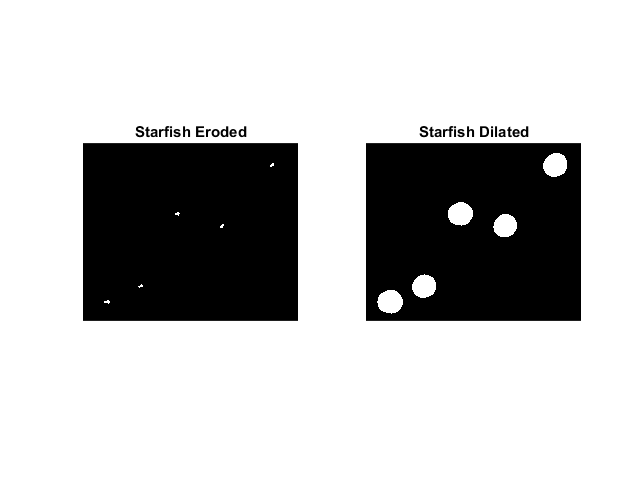

close;

% strel value set to disk with the radius of 7
% strel value set to sphere with the radios of 30
se_disk_3 = strel('disk',7);
se_sphere_3 = strel('sphere',20);

% Couple of image have erroneous objects that get through separator
% function, this makes sure that those pixels are removed then the starifhs
% are increased in size
starfish_erode = imerode(starfish_sep, se_disk_3);
starfish_dilate = imdilate(starfish_erode, se_sphere_3);

% Showing image
figure;
hold on;
    subplot(1,2,1), imshow(starfish_erode);
    title("Starfish Eroded");
    subplot(1,2,2), imshow(starfish_dilate);
    title("Starfish Dilated");
hold off;

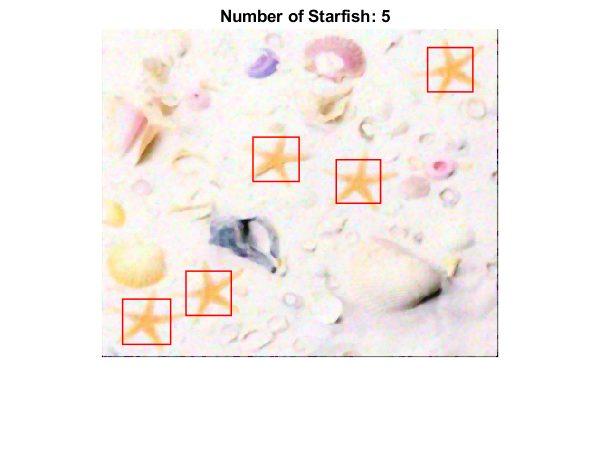

close;

% Labels connected components within the image, returns a matrix containing
% the labels (Lstarfish) and the number of objects in images
[Lstarfish, numstarfish] = bwlabel(  starfish_dilate  , 4);

% Contains the maximum elements of the array
%
% DID YOU KNOW THAT STARFISH AREN'T FISH AT ALL! 
% SCIENTISTS PREFER THE NAME SEA STAR 
starfishies = max(Lstarfish(:));
 
% Region property for bounding boxes
bounding_boxes = regionprops(Lstarfish, starfish_dilate, 'BoundingBox');

% Showing image and places the bounding boxes on the denoised image
% (clearer to see)
figure;
hold on;
    subplot(1,1,1), imshow(denoised_starfish);
    title(['Number of Starfish: ',num2str(starfishies)]);
    bounding_boxes_func(bounding_boxes);
hold off;

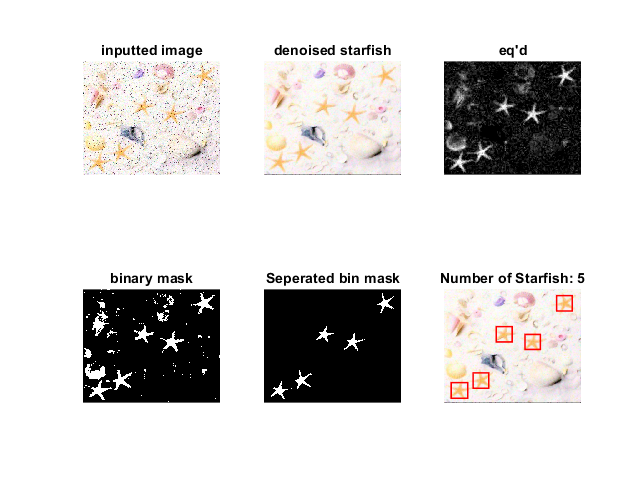

% Big figure showing all the stages
% This is mostly for the report
figure;
hold on;
    subplot(2,3,1), imshow(starfish);
    title("inputted image");
    subplot(2,3,2), imshow(denoised_starfish);
    title("denoised starfish");
    subplot(2,3,3), imshow(starfish_eq);
    title("eq'd");
    subplot(2,3,4), imshow(bin_starfish);
    title("binary mask");
    subplot(2,3,5), imshow(starfish_sep);
    title("Seperated bin mask");
    subplot(2,3,6), imshow(denoised_starfish);
    title(['Number of Starfish: ',num2str(starfishies)]);
    bounding_boxes_func(bounding_boxes);
hold off;